clear arduino;

    %connect to serial, re-run untill light tunrs on
    arduino = serialport("COM7", 115200);
    configureTerminator(arduino,"LF");

%print out serial data to make sure accel is working
serial_command(arduino, 400/10);
configureCallback(arduino,"terminator", @sample_data);
    

configureCallback(arduino, "off");
clc


num_data_points = 1000;
configureCallback(arduino, "off");
    %set up data struct to read
    arduino.UserData = struct("Data",zeros(num_data_points,3),"Count",1, "Points", num_data_points);
    
    serial_command(arduino, num_data_points/10);
    configureTerminator(arduino,"CR");
    flush(arduino);
    configureCallback(arduino,"terminator", @read_data);


    %clear arduino

configureCallback(arduino, "off");
    arduino.UserData.Data

ans =          880        2912    60000000
        1767        2976    60000000
        2662        2988    60000000
        3549        3064    60000000
        4436        3136    60000000
        5323        3188    60000000
        6210        3120    60000000
        7097        3056    60000000
        7984        3036    60000000
        8871        3036    60000000


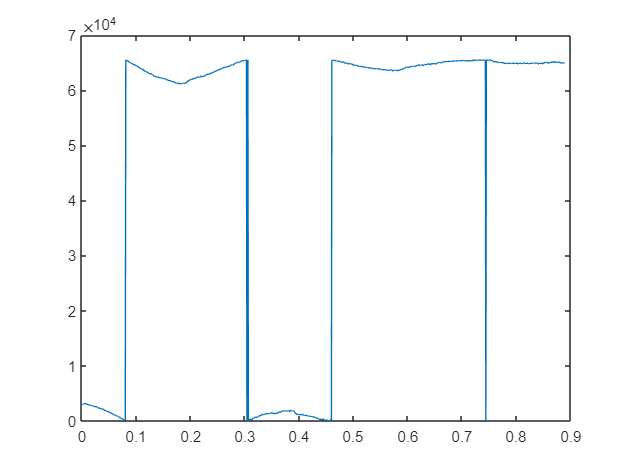

offset = max(arduino.UserData.Data(i, 2))
for  i = 1:length(arduino.UserData.Data(:,2))
    if arduino.UserData.Data(i, 2) > 20
        arduino.UserData.Data(i, 2) = arduino.UserData.Data(i, 2) - offset;
    end
end


figure(1)
clf
plot(arduino.UserData.Data(:,1)/1000000,arduino.UserData.Data(:,2))

serialportlist("available")

ans = "COM3"

clf
h = animatedline('MaximumNumPoints',100);
axis([0,4*pi,-1,1])

x = linspace(0,4*pi,1000);
y = sin(x);
for k = 1:length(x)
    addpoints(h,x(k),y(k));
    drawnow
end

figure(1)
clf
plot(arduino.UserData.Data(good_data,1),arduino.UserData.Data(good_data,2))


clear arduino

clear arduino


    %connect to serial
    arduino = serialport("COM7",9600);
    %set up line terminator
    configureTerminator(arduino,"CR/LF");
    %clear serial buffer
    flush(arduino);
    %set up data struct to read
    arduino.UserData = struct("Data",[],"Count",1);
    %run func. every time the "terminator
    % is detected


  configureCallback(arduino,"terminator", @read_data);
    


    

    function sample_data(src, ~)
    % Read the ASCII data from the serialport object.
    readline(src)
    end


    function read_data(src, ~)
    % Read the ASCII data from the serialport object.

    data = readline(src);

    data = split(data);
    data = str2double(data);

     %Convert the string data to numeric type and save it in the UserData
     %property of the serialport object.
     src.UserData.Data(src.UserData.Count,:) = [data(1) data(2) data(3)];
 
     % Update the Count value of the serialport object.
     src.UserData.Count = src.UserData.Count + 1;

  
     % If 1001 data points have been collected from the Arduino, switch off the
     % callbacks and plot the data.
         if src.UserData.Count > src.UserData.Points
            configureCallback(src, "off");
         end
    end

